# MULTIBODY SYSTEMS SOLUTIONS

The solution follows a standardized pipeline, consisting of one setup phase and 4 system solution phases:

- **0) Multibody sys. data and definition**: where we set the workspace up and define the main unknows we'll use in the following steps

- **1) Kinematic equations**

-     a. Linear graph definition

-     b. K.E. of bodies

-     c. K.E. of joints

-     d. K.E. of arm-links

- **2) Loop (constraint) equations**

-     a. T-Tree and R-Tree definition

-     b. Actual (fundamental) loops identification and solutions

- **3) Dynamics equations**

-     A. Constitutive equations

-     B. Node balance equations: Force and moment balances (Newton-Euler dynamics

- **4) Final equations of motion assembly**

## EX1 - Four bar linkage with slider (from slides)

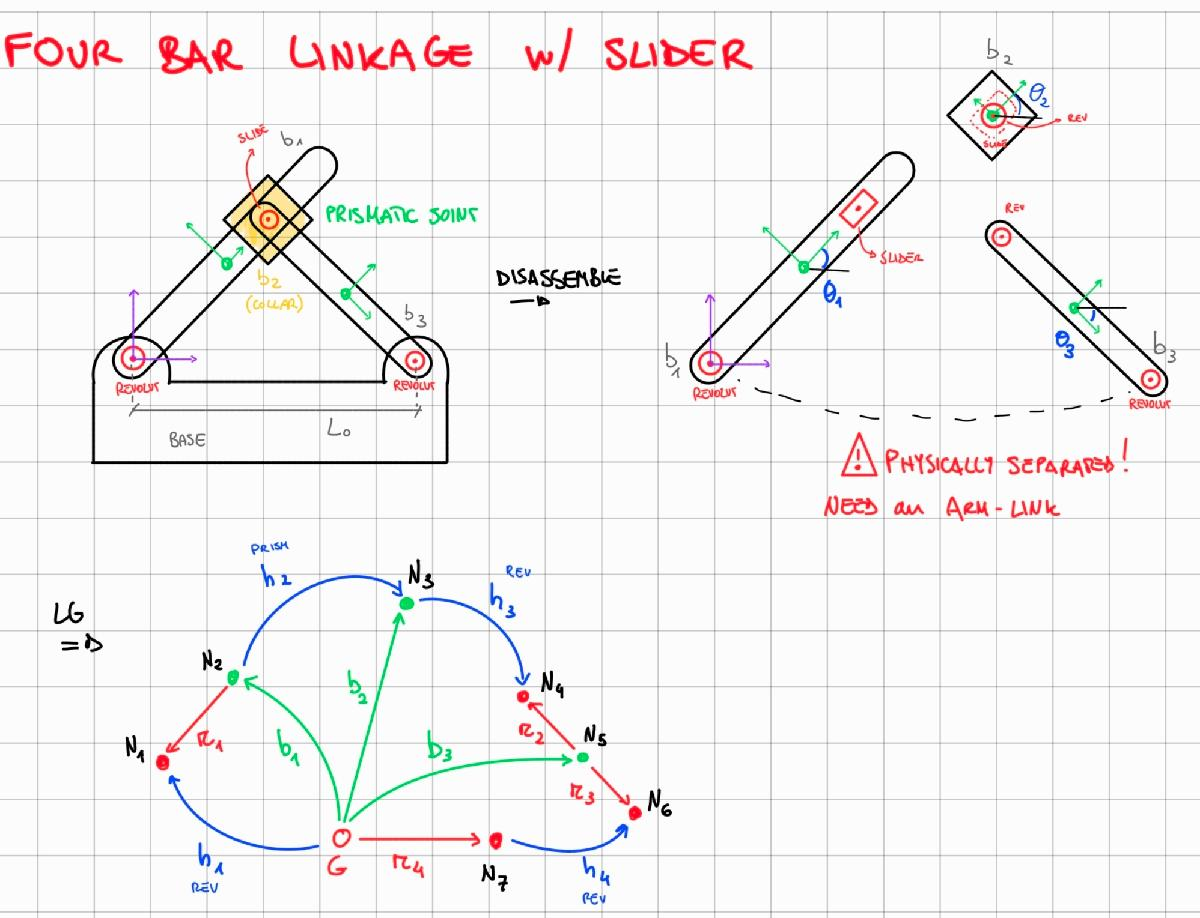

### 0) Sytem data and definition

clear;
close all;
clc;
addpath("MBLibs/");

syms t

Main system unknowns

syms theta1(t) theta2(t) theta3(t) % Bodies' rotation angles (absolute)
syms x1(t) y1(t) x2(t) y2(t) x3(t) y3(t) % Bodies' absolute coordinates
syms theta_j1(t) theta_j2(t) theta_j3(t) theta_j4(t) s(t) % Joints local rot. ang. and slider position 

% Parameters (given by exercise)
syms L_0 L_1 L_3

### 1) Kinematic equations

We start by defining the generic constitutive equations for bodies, joints and arm-links

- Constitutive equations of **bodies**: 

-     Rotation matrices of body frame with absolute angles 

-     Vector between body reference frame origin and ground frame origin in absolute coordinates

- Constitutive equations of** arm links**:

-     Auxliary reference frame (vector plus, if any, rotation matrix) between the body frame and the auxiliary frame

-     Project the vector into absolute coordinates using body rotation matrix

- Constitutive equations of the **joints **--> either:

-     the allowed relative translations and rotations (i.e. vector and rotation matrix)

-     or the condtions that imposes the relative motion restriction

**!! NOTE !!**

From here on, the **Recursive** approach to LG (and T-Tree) definition is employed, which mean we'll define kinematic equations wrt joint angles;

subsequently we'll define the R-Tree by including bodies as branches and joints as chords to derive relationships between local joint angles $\theta_{J_i}$ and absolute rotation angles $\theta_i$

#### Bodies

B1 (left bar)

R1 = rotate3('Z', theta1)

$$R1 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

b1 = [x1; y1; 0]    % Like r_b1 in the notes

$$b1(t) = \left(\begin{array}{c} x_{1}\left(t\right)\\ y_{1}\left(t\right)\\ 0 \end{array}\right)$$

B2 (sliding collar)

R2 = rotate3('Z', theta2)
b2 = [x2; y2; 0]

$$R2 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

B3 (right bar)

R3 = rotate3('Z', theta3)

$$b2(t) = \left(\begin{array}{c} x_{2}\left(t\right)\\ y_{2}\left(t\right)\\ 0 \end{array}\right)$$

b3 = [x3; y3; 0]

#### Joints

**NOTE: the joint allowed relative translation vectors r_hi should always be projected on local (body) reference frame using rotation matrices, but if they don't allow transl. then r_hi = hi**

J1: Revolute joint, connects b1 with the baseplate (where ground frame is)

RJ1 = rotate3('Z', theta_j1)

$$R3 = \left(\begin{array}{ccc} \cos\left(\theta_{3}\left(t\right)\right) & -\sin\left(\theta_{3}\left(t\right)\right) & 0\\ \sin\left(\theta_{3}\left(t\right)\right) & \cos\left(\theta_{3}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

h1 = zeros(3,1)

$$b3(t) = \left(\begin{array}{c} x_{3}\left(t\right)\\ y_{3}\left(t\right)\\ 0 \end{array}\right)$$

J2: Prismatic joint on sliding collar, slides along x axis of B1

RJ2 = RJ1 % the local joint angles are the same, so their rotation matrices are the same
r_h2 = [s(t);0;0]; % allowed translation along x axis
% Walking along kinematic chain we see that h2 has to be corrected to
% account for rotation

$$RJ1 = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{j1}}\left(t\right)\right) & -\sin\left(\theta_{\mathrm{j1}}\left(t\right)\right) & 0\\ \sin\left(\theta_{\mathrm{j1}}\left(t\right)\right) & \cos\left(\theta_{\mathrm{j1}}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

h2 = RJ2 * r_h2

h1 =      0
     0
     0


J3: Revolute joint, connects slider on B1 with B3w

RJ3 = rotate3('Z', theta_j3)
h3 = zeros(3,1)

$$RJ2 = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{j1}}\left(t\right)\right) & -\sin\left(\theta_{\mathrm{j1}}\left(t\right)\right) & 0\\ \sin\left(\theta_{\mathrm{j1}}\left(t\right)\right) & \cos\left(\theta_{\mathrm{j1}}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

J4: Revolute joint, connects B3 with baseplate

RJ4 = rotate3('Z', theta_j4)
h4 = zeros(3,1)

#### Arm-links

We can identify the T-Tree first (cutting joints if necessary) to correctly define the rotations of the arm-links wrt the joint rotations

**T-Tree with recursive approach**

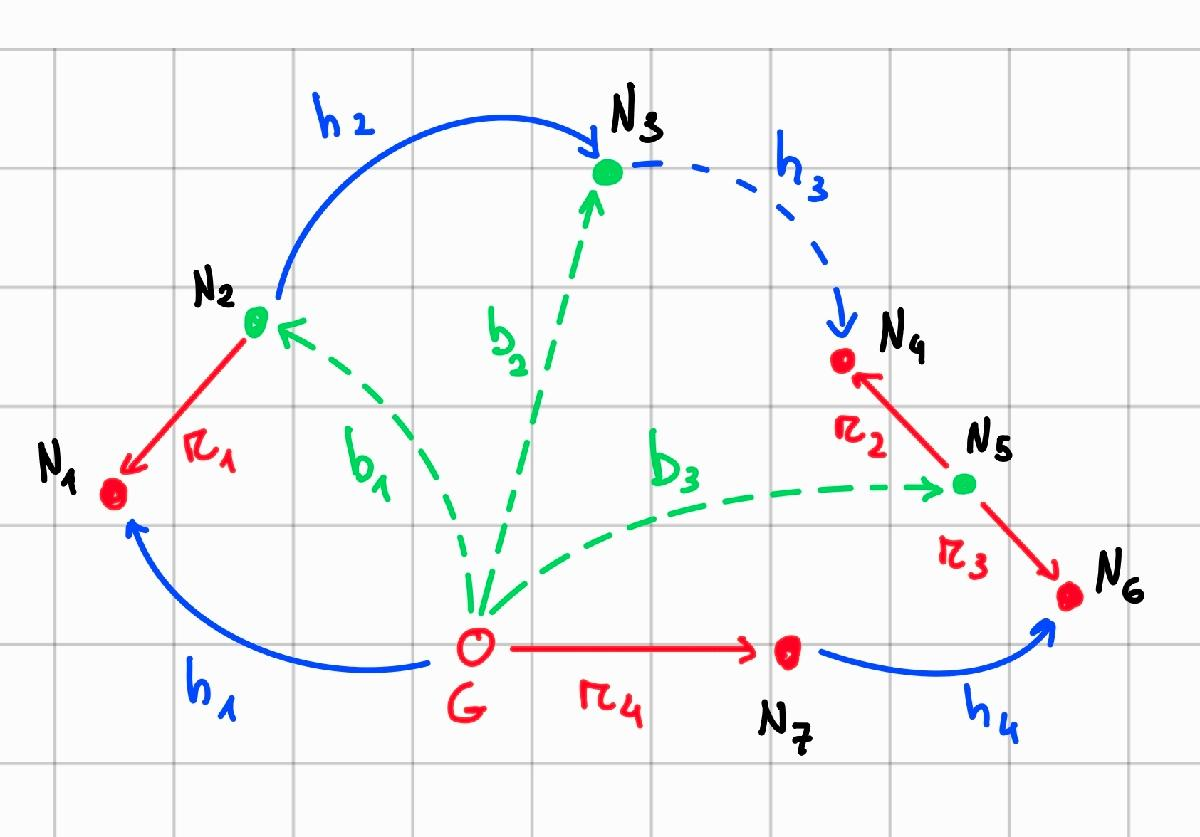

**NOTE:** arm-links don't inherently carry rotation matrices in their transfomation mat. ($R_{r_i} \equiv Id$), but to express $r_i$ in global reference we need to relate their rotations with joint rotations:

to do so walk along the (cut) kinematic chain and chain-multiply joint rotations by $r_{a_i}$

r1:

r_a1 = [-L_1/2; 0; 0]

$$h2 = \left(\begin{array}{c} \cos\left(\theta_{\mathrm{j1}}\left(t\right)\right)\,s\left(t\right)\\ \sin\left(\theta_{\mathrm{j1}}\left(t\right)\right)\,s\left(t\right)\\ 0 \end{array}\right)$$

r1 = RJ1*r_a1       % derived by walking k. chain L->R

r2:

r_a2 = [-L_3/2; 0; 0]

$$RJ3 = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{j3}}\left(t\right)\right) & -\sin\left(\theta_{\mathrm{j3}}\left(t\right)\right) & 0\\ \sin\left(\theta_{\mathrm{j3}}\left(t\right)\right) & \cos\left(\theta_{\mathrm{j3}}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

r2 = RJ4*r_a2       % derived by walking k. chain R->L

h3 =      0
     0
     0


r3:

r_a3 = [L_3/2; 0; 0]
r3 = RJ4*r_a3       % same as r2

$$RJ4 = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{j4}}\left(t\right)\right) & -\sin\left(\theta_{\mathrm{j4}}\left(t\right)\right) & 0\\ \sin\left(\theta_{\mathrm{j4}}\left(t\right)\right) & \cos\left(\theta_{\mathrm{j4}}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

r4:

r4 = [L_0; 0; 0] % no rotation

h4 =      0
     0
     0


### 2) Loop equations

#### **R-Tree**

Find solutions for joint angles wrt global angles

Phi_thetaJ1 = theta_j1 == theta1;
Phi_thetaJ2 = theta2 == theta1;
Phi_thetaJ3 = theta_j3 == theta3 - theta2;
Phi_thetaJ4 = theta_j4 == theta3;

% combined solutions for all joint angles
Phi_thetaJi = [Phi_thetaJ1; Phi_thetaJ2; Phi_thetaJ3; Phi_thetaJ4]

#### T-Tree

Here we cut the revolute joint h3 so we can write the loop equation wrt h3

eq_cut = h1 - r1 + h2 + h3 - r2 + r3 - h4 - r4

$$r\_a1 = \left(\begin{array}{c} -\frac{L_{1}}{2}\\ 0\\ 0 \end{array}\right)$$

The translational loop vector of the joint must be projected into the reaction space of the joint h3:

!! NOTE: the joint is connected to a moving body (B3), not fixed to the ground, so we pull the motion and reaction space vectors from the reference body's rotation matrix

ja_X = get_unit_vector3('X', R3);

$$r1 = \left(\begin{array}{c} -\frac{L_{1}\,\cos\left(\theta_{\mathrm{j1}}\left(t\right)\right)}{2}\\ -\frac{L_{1}\,\sin\left(\theta_{\mathrm{j1}}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

ja_Y = get_unit_vector3('Y', R3);
Phi_X = simplify(expand(eq_cut.'*ja_X))

$$r\_a2 = \left(\begin{array}{c} -\frac{L_{3}}{2}\\ 0\\ 0 \end{array}\right)$$

Phi_Y = simplify(expand(eq_cut.'*ja_Y));

$$r2 = \left(\begin{array}{c} -\frac{L_{3}\,\cos\left(\theta_{\mathrm{j4}}\left(t\right)\right)}{2}\\ -\frac{L_{3}\,\sin\left(\theta_{\mathrm{j4}}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

Now we subsistute the joint angles given $\Phi_{\theta_{J_i}}$

Phi_abs_X = subs(Phi_X, lhs(Phi_thetaJi), rhs(Phi_thetaJi))
Phi_abs_Y = subs(Phi_Y, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$r\_a3 = \left(\begin{array}{c} \frac{L_{3}}{2}\\ 0\\ 0 \end{array}\right)$$

Find the analytical solution for s(t)

syms y

$$r3 = \left(\begin{array}{c} \frac{L_{3}\,\cos\left(\theta_{\mathrm{j4}}\left(t\right)\right)}{2}\\ \frac{L_{3}\,\sin\left(\theta_{\mathrm{j4}}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

tmp = subs(Phi_abs_X, s, y);
sol_s_X = solve(tmp, y)

$$r4 = \left(\begin{array}{c} L_{0}\\ 0\\ 0 \end{array}\right)$$

tmp = subs(Phi_abs_Y, s, y);
sol_s_Y = solve(tmp, y)

**!!! NOTE:** If it is not possible to solve it analytically it will be added to the DAE system of equations of dynamics

### CoM Kinematics

**NOTE:** This step is only relevant if exercise asks to predict *time response*, natural frequencies, or anything requiring integration over time;

**Skip** if quasi-static analysis is applicable, i.e. when

- the mechanism moves slowly enough that `m·a` and `I·α` are negligible next to the other forces at play (springs, friction, applied loads)

- or you're deliberately asking a narrower question ("what reaction force does the pin see *right now*, at this configuration?") rather than "how does this system evolve over time?"

Set up the kinematics of the centers of mass of all the bodies to use later in the dynamics

B1

G1_pre = h1-r1; % Position of CoM before subsituting the angle solution
% Position
G1 = subs(G1_pre, lhs(Phi_thetaJi), rhs(Phi_thetaJi))
% Velocity as integration of G1
VG1 = diff(G1, t);

$$Phi\_thetaJi(t) = \left(\begin{array}{c} \theta_{\mathrm{j1}}\left(t\right)=\theta_{1}\left(t\right)\\ \theta_{2}\left(t\right)=\theta_{1}\left(t\right)\\ \theta_{\mathrm{j3}}\left(t\right)=\theta_{3}\left(t\right)-\theta_{2}\left(t\right)\\ \theta_{\mathrm{j4}}\left(t\right)=\theta_{3}\left(t\right) \end{array}\right)$$

% Acceleration
AG1 = diff(VG1, t);
% Angular velocity

$$eq\_cut = \left(\begin{array}{c} \cos\left(\theta_{\mathrm{j1}}\left(t\right)\right)\,s\left(t\right)-L_{0}+\frac{L_{1}\,\cos\left(\theta_{\mathrm{j1}}\left(t\right)\right)}{2}+L_{3}\,\cos\left(\theta_{\mathrm{j4}}\left(t\right)\right)\\ \frac{L_{1}\,\sin\left(\theta_{\mathrm{j1}}\left(t\right)\right)}{2}+L_{3}\,\sin\left(\theta_{\mathrm{j4}}\left(t\right)\right)+\sin\left(\theta_{\mathrm{j1}}\left(t\right)\right)\,s\left(t\right)\\ 0 \end{array}\right)$$

tmp = simplify(R1.'*diff(R1,t)); % Skew symmetric matrix for angular velocity
ang_vel1 = [tmp(3,2); tmp(1,3); tmp(2,1)] % Extract angular velocity vector elements from SSM

**NOTE**: Cayley's formula to map skew symmetric matrix onto any rotation matrix

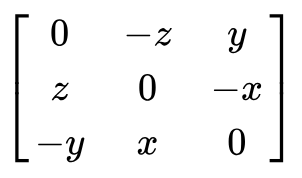

B2

G2_pre = -r1+h2;

$$Phi\_X = s\left(t\right)\,\cos\left(\theta_{3}\left(t\right)-\theta_{\mathrm{j1}}\left(t\right)\right)+\frac{L_{1}\,\cos\left(\theta_{3}\left(t\right)-\theta_{\mathrm{j1}}\left(t\right)\right)}{2}+L_{3}\,\cos\left(\theta_{3}\left(t\right)-\theta_{\mathrm{j4}}\left(t\right)\right)-L_{0}\,\cos\left(\theta_{3}\left(t\right)\right)$$

% Position
G2 = subs(G2_pre, lhs(Phi_thetaJi), rhs(Phi_thetaJi))
% Velocity

$$Phi\_abs\_X = L_{3}+s\left(t\right)\,\cos\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)+\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)}{2}-L_{0}\,\cos\left(\theta_{3}\left(t\right)\right)$$

VG2 = diff(G2, t);

$$Phi\_abs\_Y = L_{0}\,\sin\left(\theta_{3}\left(t\right)\right)+\sin\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)\,s\left(t\right)+\frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)}{2}$$

% Acceleration
AG2 = diff(VG2, t);
% Angular velocity
tmp = simplify(R2.'*diff(R2,t));

$$sol\_s\_X = -\frac{L_{3}+\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)}{2}-L_{0}\,\cos\left(\theta_{3}\left(t\right)\right)}{\cos\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)}$$

ang_vel2 = [tmp(3,2); tmp(1,3); tmp(2,1)]

B3

G3_pre = r4+h4-r3;

$$sol\_s\_Y = -\frac{L_{0}\,\sin\left(\theta_{3}\left(t\right)\right)+\frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)}{2}}{\sin\left(\theta_{1}\left(t\right)-\theta_{3}\left(t\right)\right)}$$

% Position
G3 = subs(G3_pre, lhs(Phi_thetaJi), rhs(Phi_thetaJi))
% Velocity
VG3 = diff(G3, t);
% Acceleration
AG3 = diff(VG3, t);
% Angular velocity
tmp = simplify(R3.'*diff(R3,t));
ang_vel3 = [tmp(3,2); tmp(1,3); tmp(2,1)]

### 3) Equations of Dynamics

- **Body**: Newton-Euler equations (force-moment balances) per-node.

-     The Newton equations (i.e. translational balance) are defined in ground frame

-     The *Euler equations* (i.e. moment balance) are defined in *body frame*

- **Joint**: the constitutive equations of joints from dynamic point of view corresponde to the definition of the reaction forces in the reaction space.

#### Constitutive eq. of Bodies

B1 (left arm)

syms Fbx_1 Fby_1 Iz1 m1 Tbz_1

$$G1 = \left(\begin{array}{c} \frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)}{2}\\ \frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

% Total forces on the body (placeholders for now)
Fb1 = [Fbx_1; Fby_1; 0];
% Total torques on the body (placeholders for now)
Tb1 = [0; 0; Tbz_1];

Newton-Euler for B1:

% Newton eq (force balance) including weight --> GLOBAL FRAME
eqn_N1 = m1*AG1 == Fb1
% Euler eq (moment balance) -->  BODY FRAME

$$ang\_vel1 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)$$

eqn_E1 = Iz1*diff(ang_vel1,t) == Tb1

B2 (sliding collar)

syms Fbx_2 Fby_2 Iz2 m2 Tbz_2
% Total forces on the body (placeholders for now)
Fb2 = [Fbx_2; Fby_2; 0];
% Total torques on the body (placeholders for now)
Tb2 = [0; 0; Tbz_2];

$$G2 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,s\left(t\right)+\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)}{2}\\ \frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)}{2}+\sin\left(\theta_{1}\left(t\right)\right)\,s\left(t\right)\\ 0 \end{array}\right)$$

Newton-Euler for B1:

% Newton eq (force balance) including weight --> GLOBAL FRAME
eqn_N2 = m2*AG2 == Fb2
% Euler eq (moment balance) -->  BODY FRAME
eqn_E2 = Iz2*diff(ang_vel2,t) == Tb2

B3 (right arm)

syms Fbx_3 Fby_3 Iz3 m3 Tbz_3
% Total forces on the body (placeholders for now)

$$ang\_vel2 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$

Fb3 = [Fbx_3; Fby_3; 0];
% Total torques on the body (placeholders for now)
Tb3 = [0; 0; Tbz_3];

Newton-Euler for B3:

% Newton eq (force balance) including weight --> GLOBAL FRAME

$$G3 = \left(\begin{array}{c} L_{0}-\frac{L_{3}\,\cos\left(\theta_{3}\left(t\right)\right)}{2}\\ -\frac{L_{3}\,\sin\left(\theta_{3}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

eqn_N3 = m3*AG3 == Fb3
% Euler eq (moment balance) -->  BODY FRAME
eqn_E3 = Iz3*diff(ang_vel3,t) == Tb3

#### Constitutive eq. of Joints

Reaction forces/moments defined in reaction space and projected in ground frame

J1 (revolute)

syms R_x1 R_y1
Fj1 = RJ1*[R_x1; R_y1; 0];
Fj1 = subs(Fj1, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

J2 (prismatic)

syms N_j2 T_j2

$$ang\_vel3 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{3}\left(t\right) \end{array}\right)$$

Fj2 = RJ2*[0; N_j2; 0]; % Restricts only y-axis movement
Fj2 = subs(Fj2, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

Tj2 = RJ2*[0; 0; T_j2]; % Restricts rotation around z
Tj2 = subs(Tj2, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

J3 (revolute)

syms R_x3 R_y3
Fj3 = RJ3*[R_x3; R_y3; 0];
Fj3 = subs(Fj3, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

J4 (revolute)

syms R_x4 R_y4
Fj4 = RJ4*[R_x4; R_y4; 0];

$$eqn\_N1 = \begin{array}{l} \left(\begin{array}{c} -m_{1}\,\left(\frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{2}+\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}}{2}\right)={\mathrm{Fbx}}_{1}\\ -m_{1}\,\left(\frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}}{2}-\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{2}\right)={\mathrm{Fby}}_{1}\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$

Fj4 = subs(Fj4, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

#### Constitutive eq. of External forces/torque drivers

syms g

$$eqn\_E1 = \left(\begin{array}{c} 0=0\\ 0=0\\ {\mathrm{Iz}}_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)={\mathrm{Tbz}}_{1} \end{array}\right)$$

j0 = [0;1;0]; % Unit vector along y-axis
% Weights of the three bodies (already in ground frame)
W1 = -m1*g*j0;
W2 = -m2*g*j0;
W3 = -m3*g*j0;
% If any external torques --> define in body frame and then PROJECT on gnd
% frame

### Node equations

In the node balance (cut-set) we assume positive the forces when the enter into the cut-set (drawn around the body). So if the edges of the graph enter into the cutset the force is taken positive.

#### **Newton equations (translational balance)  ("N")**

B1 (node N2)

eqn_node2_N = Fb1 + W1 + Fj1 - Fj2;
% Solution in Fb1

$$eqn\_N2 = \begin{array}{l} \left(\begin{array}{c} -m_{2}\,\left(\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}}{2}-\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{3}+2\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}s\left(t\right)+\frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{2}}{2}+\cos\left(\theta_{1}\left(t\right)\right)\,s\left(t\right)\,\sigma_{1}+\sin\left(\theta_{1}\left(t\right)\right)\,s\left(t\right)\,\sigma_{2}\right)={\mathrm{Fbx}}_{2}\\ m_{2}\,\left(\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{3}-\frac{L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}}{2}+2\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}s\left(t\right)+\frac{L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{2}}{2}-\sin\left(\theta_{1}\left(t\right)\right)\,s\left(t\right)\,\sigma_{1}+\cos\left(\theta_{1}\left(t\right)\right)\,s\left(t\right)\,\sigma_{2}\right)={\mathrm{Fby}}_{2}\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}s\left(t\right) \end{array}$$

sol_Fb1 = solve([eqn_node2_N(1), eqn_node2_N(2)], [Fbx_1, Fby_1])

B2 (node N3)

eqn_node3_N = Fb2 + W2 + Fj2 - Fj3;

$$eqn\_E2 = \left(\begin{array}{c} 0=0\\ 0=0\\ {\mathrm{Iz}}_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)={\mathrm{Tbz}}_{2} \end{array}\right)$$

% Solution in Fb2
sol_Fb2 = solve([eqn_node3_N(1), eqn_node3_N(2)], [Fbx_2, Fby_2])

B3 (node N5)

eqn_node5_N = Fb3 + W3 + Fj3 + Fj4;
% Solution in Fb3
sol_Fb3 = solve([eqn_node5_N(1), eqn_node5_N(2)], [Fbx_3, Fby_3])

#### Euler equations (rotational balance) ("E")

B1 (node N2)

Tj1 = inv_rot_mat(R1)*(skew_matrix(r1)*Fj1);
eqn_node2_E = simplify(Tb1 + Tj1 - Tj2);

$$eqn\_N3 = \begin{array}{l} \left(\begin{array}{c} m_{3}\,\left(\frac{L_{3}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{2}+\frac{L_{3}\,\cos\left(\theta_{3}\left(t\right)\right)\,\sigma_{1}}{2}\right)={\mathrm{Fbx}}_{3}\\ m_{3}\,\left(\frac{L_{3}\,\sin\left(\theta_{3}\left(t\right)\right)\,\sigma_{1}}{2}-\frac{L_{3}\,\cos\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{2}\right)={\mathrm{Fby}}_{3}\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)}^{2} \end{array}$$

% Solution in Tb1
sol_Tb1 = solve(eqn_node2_E(3), Tbz_1) % Solve 3rd equation since it corresponds to torque around Z-axis

$$eqn\_E3 = \left(\begin{array}{c} 0=0\\ 0=0\\ {\mathrm{Iz}}_{3}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)={\mathrm{Tbz}}_{3} \end{array}\right)$$

B2 (node N3)

eqn_node3_E = simplify(Tb2 + Tj2);
% Sol in Tb2
sol_Tb2 = solve(eqn_node3_E(3), Tbz_2)

B3 (node N5)

Tj3 = inv_rot_mat(R2)*(skew_matrix(r2)*Fj3);

$$Fj1 = \left(\begin{array}{c} R_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)-R_{\mathrm{y1}}\,\sin\left(\theta_{1}\left(t\right)\right)\\ R_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)+R_{\mathrm{y1}}\,\cos\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

Tj4 = inv_rot_mat(R2)*(skew_matrix(r3)*Fj4);
eqn_node5_E = simplify(Tb3 + Tj3 + Tj4);
% Solution in Tb3
sol_Tb3 = solve(eqn_node5_E(3), Tbz_3)

$$Fj2 = \left(\begin{array}{c} -N_{\mathrm{j2}}\,\sin\left(\theta_{1}\left(t\right)\right)\\ N_{\mathrm{j2}}\,\cos\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

### 4) Assembling the DAE system: final equations of motion

Substitute the found solutions of the node equations into the constitutive N-E dynamics equations

% [ (all Newton equations); (all Euler equations) ]
tmp = [ eqn_N1(1:2);...
        eqn_N2(1:2);...

$$Tj2 = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{j2}} \end{array}\right)$$

        eqn_N3(1:2);...
        eqn_E1(3);...
        eqn_E2(3);...
        eqn_E3(3)

$$Fj3 = \left(\begin{array}{c} R_{\mathrm{x3}}\,\cos\left(\theta_{2}\left(t\right)-\theta_{3}\left(t\right)\right)+R_{\mathrm{y3}}\,\sin\left(\theta_{2}\left(t\right)-\theta_{3}\left(t\right)\right)\\ R_{\mathrm{y3}}\,\cos\left(\theta_{2}\left(t\right)-\theta_{3}\left(t\right)\right)-R_{\mathrm{x3}}\,\sin\left(\theta_{2}\left(t\right)-\theta_{3}\left(t\right)\right)\\ 0 \end{array}\right)$$

];
% Substitute solutions of node eq.
tmp = subs(tmp, sol_Fb1);
tmp = subs(tmp, sol_Fb2);

$$Fj4 = \left(\begin{array}{c} R_{\mathrm{x4}}\,\cos\left(\theta_{3}\left(t\right)\right)-R_{\mathrm{y4}}\,\sin\left(\theta_{3}\left(t\right)\right)\\ R_{\mathrm{x4}}\,\sin\left(\theta_{3}\left(t\right)\right)+R_{\mathrm{y4}}\,\cos\left(\theta_{3}\left(t\right)\right)\\ 0 \end{array}\right)$$

tmp = subs(tmp, sol_Fb3);
tmp = subs(tmp, Tbz_1, sol_Tb1);
tmp = subs(tmp, Tbz_2, sol_Tb2);
% Final system of ODEs
ode_eqns = subs(tmp, Tbz_3, sol_Tb3);
ode_eqns = simplify(subs(ode_eqns, lhs(Phi_thetaJi), rhs(Phi_thetaJi)));

Now define the algebraic equations;

In our case, only prismatic slider position $s(t)$ is defined with an algebraic equation:

alg_eqns = [sol_s_X == s(t); sol_s_Y == s(t)];
diff_alg_eqns = diff(alg_eqns, t,t);

#### Final DAE system

DAE_eqns = [ode_eqns; diff_alg_eqns]

Reaction variables

rvars = [R_x1 R_y1 N_j2 T_j2 R_x3 R_y3 R_x4 R_y4];

sol_Fb1 = struct with fields:
    Fbx_1: R_y1*sin(theta1(t)) - N_j2*sin(theta1(t)) - R_x1*cos(theta1(t))
    Fby_1: g*m1 - R_x1*sin(theta1(t)) + N_j2*cos(theta1(t)) - R_y1*cos(theta1(t))


System unknowns

xvars = [theta1(t), theta3(t), s(t)];

Set of DAE vars:

DAE_vars = [xvars rvars]

sol_Fb2 = struct with fields:
    Fbx_2: N_j2*sin(theta1(t)) + R_x3*cos(theta2(t) - theta3(t)) + R_y3*sin(theta2(t) - theta3(t))
    Fby_2: g*m2 + R_y3*cos(theta2(t) - theta3(t)) - R_x3*sin(theta2(t) - theta3(t)) - N_j2*cos(theta1(t))


% Check system consistency
disp(length(DAE_vars) == length(DAE_eqns))

#### Direct kinematics solution (given non-driven system)

Now substitute dummy variables for second derivative of thetai(t) and s(t) to find angular and linear accelerations of b1, b2 and b3 + dummy non-time dependant s variable

syms a1 a2 a3 s_prism

sol_Fb3 = struct with fields:
    Fbx_3: R_y4*sin(theta3(t)) - R_x3*cos(theta2(t) - theta3(t)) - R_y3*sin(theta2(t) - theta3(t)) - R_x4*cos(theta3(t))
    Fby_3: g*m3 - R_x4*sin(theta3(t)) - R_y3*cos(theta2(t) - theta3(t)) + R_x3*sin(theta2(t) - theta3(t)) - R_y4*cos(theta3(t))


tmp = subs(DAE_eqns, [diff(theta1(t),t,t), diff(s(t),t,t), diff(theta3(t),t,t), s(t)], [a1, a2, a3, s_prism])
solve(tmp, [a1, a2, a3, s_prism, rvars])

$$sol\_Tb1 = T_{\mathrm{j2}}+\frac{L_{1}\,\cos\left(\theta_{\mathrm{j1}}\left(t\right)\right)\,\left(R_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)+R_{\mathrm{y1}}\,\cos\left(\theta_{1}\left(t\right)\right)\right)}{2}+\frac{L_{1}\,\sin\left(\theta_{\mathrm{j1}}\left(t\right)\right)\,\left(R_{\mathrm{y1}}\,\sin\left(\theta_{1}\left(t\right)\right)-R_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\right)}{2}$$

$$sol\_Tb2 = -T_{\mathrm{j2}}$$

$$sol\_Tb3 = \frac{L_{3}\,R_{\mathrm{y3}}\,\cos\left(\theta_{2}\left(t\right)-\theta_{3}\left(t\right)+\theta_{\mathrm{j4}}\left(t\right)\right)}{2}-\frac{L_{3}\,R_{\mathrm{x4}}\,\sin\left(\theta_{3}\left(t\right)-\theta_{\mathrm{j4}}\left(t\right)\right)}{2}-\frac{L_{3}\,R_{\mathrm{x3}}\,\sin\left(\theta_{2}\left(t\right)-\theta_{3}\left(t\right)+\theta_{\mathrm{j4}}\left(t\right)\right)}{2}-\frac{L_{3}\,R_{\mathrm{y4}}\,\cos\left(\theta_{3}\left(t\right)-\theta_{\mathrm{j4}}\left(t\right)\right)}{2}$$

$$DAE\_vars = \left(\begin{array}{ccccccccccc} \theta_{1}\left(t\right) & \theta_{3}\left(t\right) & s\left(t\right) & R_{\mathrm{x1}} & R_{\mathrm{y1}} & N_{\mathrm{j2}} & T_{\mathrm{j2}} & R_{\mathrm{x3}} & R_{\mathrm{y3}} & R_{\mathrm{x4}} & R_{\mathrm{y4}} \end{array}\right)$$

   1

